# Non Linear Dynamic Inversion

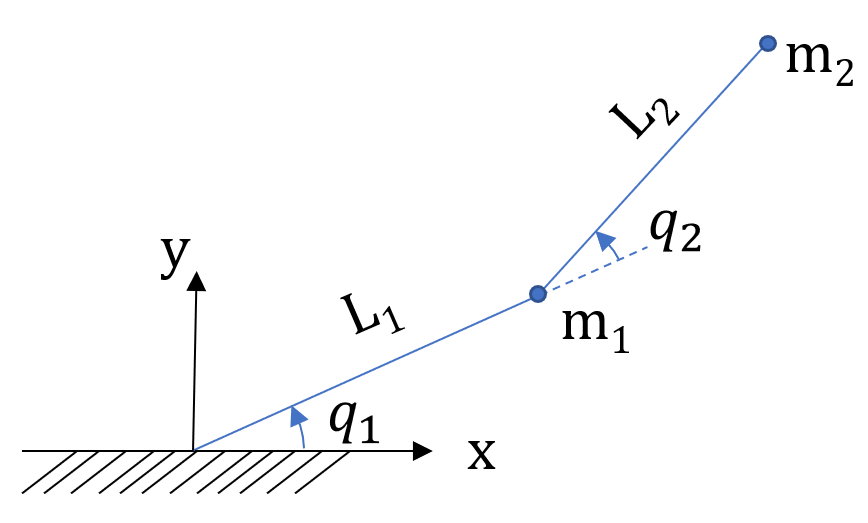

We consider a simple planar robot with two degrees of liberty:$q_1$ and $q$ actuated by two torques $\tau_1$ and $\tau_2$. The length of each arm is $L_{1,2}$ and the mass $m_{1,2}$  are located at the end of each arm. 

% Robot parameters
global R
R.m1 = 1; % Arm 1 mass
R.m2 = 1; % Arm 2 mass
R.L1 = 1; % Arm 1 length
R.L2 = 1; % Arm 2 length
R.f1 = 1; % Friction 1
R.f2 = 1; % Friction 2
R.g = -0*9.81; % Gravity (gravity neglected)

% Initial angles
q01 = 0;
q02 = 0;
q = [q01,q02]'

q =      0
     0


qdot = [0,0]'

qdot =      0
     0


The dynamic model is non linear. The differential equation is given below (functions M, C, G, F and S are given at the end of the live script):


$$M\left(q\right)\ddot{\;q} +C\left(q,\dot{\;q} \right)\dot{\;q\;} +G\left(q\right)+F\left(q,\dot{\;q} \right)=\tau \;$$


Where:

$q=\left\lbrack \begin{array}{c}
q_1 \\
q_2 
\end{array}\right\rbrack$ are the joint angles

$\tau =\left\lbrack \begin{array}{c}
\tau_1 \\
\tau_2 
\end{array}\right\rbrack$ are the joint torques

## 1. Gravity compensation

The torque must have a constant component in order to compensate for gravity and insure the position of the robot at rest.

**Question 1**: Calculate **tau0** the torque that exactly compensates the gravity for a configuration q0=q01,q02


$$G\left(q_{0\;} \right)=\tau_0 \;$$


tau0=G([0 0]')

tau0 =      0
     0


This compensating torque will be added to the control torque.

## 2. PID control assuming no coupling

We  assume there is no coupling between the joints: $\tau_1 \;$moves $q_1$ whatever arm 2 does and $\tau_2 \;$moves $q_2$ whatever arm 1 does. We also assume small angles near $\left(0,0\right)$.

The Simulink file** PIDcontrol.slx** is provided with two PID for the control of $q_1$ and $q_2$

**Question 2**: tune the PID by trial and error in order to achieve an acceptable performance (time response  3s, overshoot  10%)

Done in simulink

**Question 3: **is the closed loop system decoupled?

Yes, since feedback is only given of the respective angles to the PIDs

## 3. State feedback controller assuming no coupling

We  assume there is no coupling between the joints: $\tau_1 \;$moves $q_1$ whatever arm 2 does and $\tau_2 \;$moves $q_2$ whatever arm 1 does. We also assume small angles near $\left(0,0\right)$.

From this asumption the linearized model is obtained by taking only diagonal terms of M and neglecting q2 variation for q1 analysis and vice versa.


$$\left\lbrace \begin{array}{l}
a_1 \;\ddot{\;q_1 } +b_1 \dot{\;q_1 } +c_1 q_1 =\tau_1 \\
a_2 \ddot{\;q_1 } +b_2 \dot{\;q_2 } +c_{2\;} q_2 =\tau_2 
\end{array}\right.$$


We asume that $q$ and $\dot{\;q\;}$can be fully measured.

The closed loop system must have damping $\omega_0 =3\;\;\textrm{rad}/s$ and $\sigma =0\ldotp 7$

**Question 4**: find the values of the coefficients a1,b1,c1,a2,b2,c2 (the values of M, C,G and F are given at the end of the script

M0 = M(q)

M0 =     2.5000    0.7500
    0.7500    0.2500


a1=M0(1,1)

a1 = 2.5000

a2=M0(2,2)

a2 = 0.2500


b1=R.f1           % Coriolis terms are neglected because of linearization

b1 = 1

b2=R.f2

b2 = 1


c1=0

c1 = 0

c2=0

c2 = 0


A1 = [0 1 ; -c1/b1 -b1/a1];
B1 = [0 ; 1/a1];
C1 = [1 0];
D1 = 0;

A2 = [0 1 ; -c2/b2 -b2/a2];
B2 = [0 ; 1/a2];
C0 = [1 0 ; 0 1];
D0 = 0;

**Question 5**: design two state space controllers ($\textrm{K1},\textrm{N1}$ and $\textrm{K2},\textrm{N2}$) in order to control $q_1$ from $\tau_1$ and $q_2$ from $\tau_2$

omega = 3

omega = 3

sigma = 0.7

sigma = 0.7000


ss1 = ss(A1,B1,C0,D0);
ss2 = ss(A2,B2,C0,D0);

p = roots([1 2*sigma*omega omega^2])

p =   -2.1000 + 2.1424i
  -2.1000 - 2.1424i


K1 = place(A1,B1,p)

K1 =    22.5000    9.5000


K2 = place(A2,B2,p)

K2 =     2.2500    0.0500



sysCL1 = feedback(ss1,K1)

sysCL1 =
 
  A = 
         x1    x2
   x1     0     1
   x2    -9  -4.2
 
  B = 
        u1
   x1    0
   x2  0.4
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



sysCL2 = feedback(ss2,K2)

sysCL2 =
 
  A = 
         x1    x2
   x1     0     1
   x2    -9  -4.2
 
  B = 
       u1
   x1   0
   x2   4
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



sysCL1(1,1)

ans =
 
  A = 
         x1    x2
   x1     0     1
   x2    -9  -4.2
 
  B = 
        u1
   x1    0
   x2  0.4
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



N1 = inv(dcgain(sysCL1(1,1)))

N1 = 22.5000

N2 = inv(dcgain(sysCL2(1,1)))

N2 = 2.2500

For the closed loop simulation the Simulink file **DecoupledControl.slx** is provided

**Question 6**: is the closed loop system decoupled?

No, we observe that even when we set q02=0 with q1 = q01 + 0.1, we see a perturbation in q2. (see graph of q in simulink)

**Question 7**: compare the perfomance with two different configurations: 

- configuration 1: q01=0 and q02=0

- configuraiotn 2: q01=0 and q02=pi/2

1st case: no change in both

2nd case: coupling is observed

## 4. Non linear state space model and linearization

The system is modeled as non linear state space equation:


$$\dot{\;X} =f\left(X,\tau \;\right)$$


The state is:


$$X=\left\lbrack \begin{array}{c}
q\\
\dot{\;q} 
\end{array}\right\rbrack$$


**Question 8:** complete the skeleton of function $f\left(X,\tau \;\right)$ given at the end of script

The linearized model assumes small variation $x$ near $\textrm{X0}$ such as: $X=\textrm{X0}+x$ . The corresponding state space model is:


$$\dot{\;x\;} =A\;x+B\;\tau \;$$


with constant matrixes $A$ and $B$

The following code computes the symbolic jacobians of $f\left(X,\tau \;\right)$relatively to variables $X$ and $\tau \;$and evaluate the numerical value for a given value of X and tau

syms X0 [4 1]
syms t0 [2 1]
f(X0,t0)

ans =      0     0     0     0


A0 = jacobian(f(X0,t0),X0)

$$A0 = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

B0 = jacobian(f(X0,t0),t0);
X01 = 0;
X02 = 0;
X03 = 0;
X04 = 0;
t01 = 0;
t02 = 0;
A0 = eval(A0)

A0 =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


B0 = eval(B0)

B0 =      0     0
     0     0
     0     0
     0     0


**Question 9**: compute the linear state space model in open loop sysol

sysol = 0;%ANSWER HERE

**Question 10**: compare the eigenvalues of the linearized open loop model for two configurations:

- configuration 1: q01=0 and q02=0

- configuration 2: q01=0 and q02=pi/4

**Question 11:** compute the linearized closed loop of the system with the state feedback computed in question 3

input of gain K: q1,q2,dq1,dq2 ; output of gain K: tau1 tau 2

K = 0;%ANSWER HERE

**Question 12**: compute the linear state space model **syscl** of the system in closed loop and compare the location of the closed loop poles with what was expected according to question 3-4

TEXT AND CODE HERE

**Bonus**

The Jacobian can of course be litteraly computed with a re-organization of the quations:


$$\dot{\;x\;} =A\;x+B\;\tau \;$$



$$\frac{d}{\textrm{dt}}\left\lbrack \begin{array}{c}
q\\
\dot{\;q\;} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & I\\
{M\left(q\right)}^{-1} \frac{\partial }{\partial q}G\left(q\right) & {M\left(q\right)}^{-1} C\left(q,\dot{q} \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
q\\
\dot{\;q} 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
{M\left(q\right)}^{-1} 
\end{array}\right\rbrack \tau$$


## 5. Non Linear Dynamic Inversion

The controller is modified with a pre-controller of the type "Non Linear Dynamic Inversion". The control torque is obtained from the desired acceleration ddqc which compensates inertia, friction and coriolis term:

 input $\tau =M\left(q,\dot{\;q\;} \right)\textrm{ddqc}+C\left(q,\dot{\;q\;} \right)\dot{\;q\;} +F\left(q,\dot{\;q\;} \right)$

**Question 13**: complete the NDI block in the Simulink file **NDI.slx**

**Question 14**: with this pre-control what is now the model between ddqc and ddq? (For the design of the controller we neglect the friction term and we still assume that the gravity is correctly compensated). Design a state space controller with the same performance requirement as in chapter 3 

TEXT AND CODE HERE

## Functions must be placed at the end of the live script

Mass matrix

function M  = M(q)
% Mass matrix
global R
M = [(R.m1*R.L1^2)/4+R.m2*(R.L1^2+R.L2^2/4+R.L1*R.L2*cos(q(2))) ,  R.m2*R.L2*(R.L2+ 2*R.L1*cos(q(2)))/4
    R.m2*R.L2*(R.L2+ 2*R.L1*cos(q(2)))/4                       ,  R.m2*R.L2^2/4];
end

Coriolis term

function tauc  = Cdq(q,dq)
% Coriolis term
global R
tauc = [-R.m2*R.L1*R.L2*sin(q(2))*(dq(1)*dq(2)+dq(2)^2/2)
    R.m2*R.L1*R.L2*dq(1)^2*sin(q(2))/2];
end

function Cm  = C(q,dq)
% Convective Matrix
global R
Cm = [-R.m2*R.L1*R.L2*sin(q(2))*dq(2) -R.m2*R.L1*R.L2*sin(q(2))/2*dq(2);...
    R.m2*R.L1*R.L2*dq(1)*sin(q(2))/2 0];
end

Gravity term

function taug  = G(q)
% Gravity term
global R
%taug = [(R.m1+R.m2)*R.L1*R.g*cos(q(1))+R.m2*R.g*R.L2*cos(q(1)+q(2))
%    R.m2*R.g*R.L2*cos(q(1)+q(2))];
taug = [R.m1*R.g*R.L1*cos(q(1))/2+R.m2*R.g*(R.L2*cos(q(1)+q(2))/2+R.L1*cos(q(1)));...
    R.m2*R.g*R.L2*cos(q(1)+q(2))/2];
end

Friction

function tauf  = F(q,dq)
% Friction term
global R
tauf = [R.f1
    R.f2].*dq;
end

The following function must be completed

function dX = f(X,tau)
q = X(1:2);
dq = X(3:4);

dX(1:2) = 0;%MODIFY
dX(3:4) = 0;%MODIFY

end